%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ex4_double_well_conservative.m
%
% Conservative system:
%   m x'' + dV/dx = 0
%   V(x) = -x^2/2 + x^4/4
%
% Convert to first-order system with v = x':
%   x' = v
%   v' = -(1/m) dV/dx = -(1/m)(-x + x^3) = (1/m)(x - x^3)
%
% Goals:
%   - plot potential V(x)
%   - phase portrait in (x,v): vector field + nullclines + trajectories
%   - equilibria and local linearization
%   - (optional) energy contours: E = (m/2)v^2 + V(x)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

m = 1;  % mass

V  = @(x) -0.5*x.^2 + 0.25*x.^4;
dV = @(x) -x + x.^3;

f = @(t,z) [ z(2);
             (1/m)*(z(1) - z(1)^3) ];

% Equilibria satisfy v=0 and x-x^3=0 -> x=0,±1
eq = [ -1 0; 0 0; 1 0 ];

% Jacobian of (x',v') at (x,v):
% J = [0 1; (1/m)(1-3x^2)  0]
J = @(x,v) [0 1; (1/m)*(1-3*x^2) 0];

fprintf('Equilibria and eigenvalues:\n');

Equilibria and eigenvalues:


for i=1:size(eq,1)
    x=eq(i,1); v=eq(i,2);
    lam = eig(J(x,v));
    fprintf('  (x*,v*)=(%.1f,%.1f): eig=(%.3f, %.3f)\n', x,v, lam(1), lam(2));
end

  (x*,v*)=(-1.0,0.0): eig=(0.000, 0.000)
  (x*,v*)=(0.0,0.0): eig=(-1.000, 1.000)
  (x*,v*)=(1.0,0.0): eig=(0.000, 0.000)


fprintf('Interpretation:\n');

Interpretation:


fprintf('  (0,0): saddle (real ±).\n');

  (0,0): saddle (real ±).


fprintf('  (±1,0): centers (pure imaginary), conservative wells.\n\n');

  (±1,0): centers (pure imaginary), conservative wells.



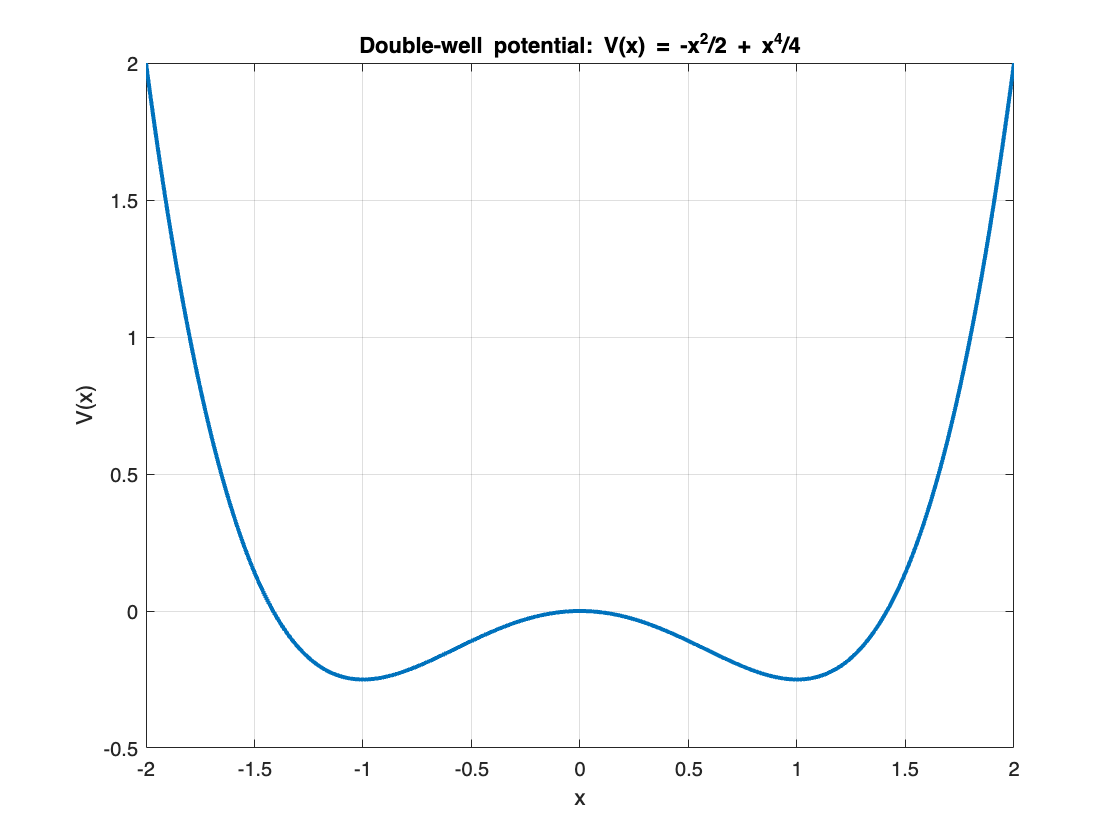


%% Plot potential
figure('Color','w','Name','Example 4: Potential');
xx = linspace(-2,2,600);
plot(xx, V(xx),'LineWidth',2); grid on; box on;
xlabel('x'); ylabel('V(x)');
title('Double-well potential: V(x) = -x^2/2 + x^4/4');

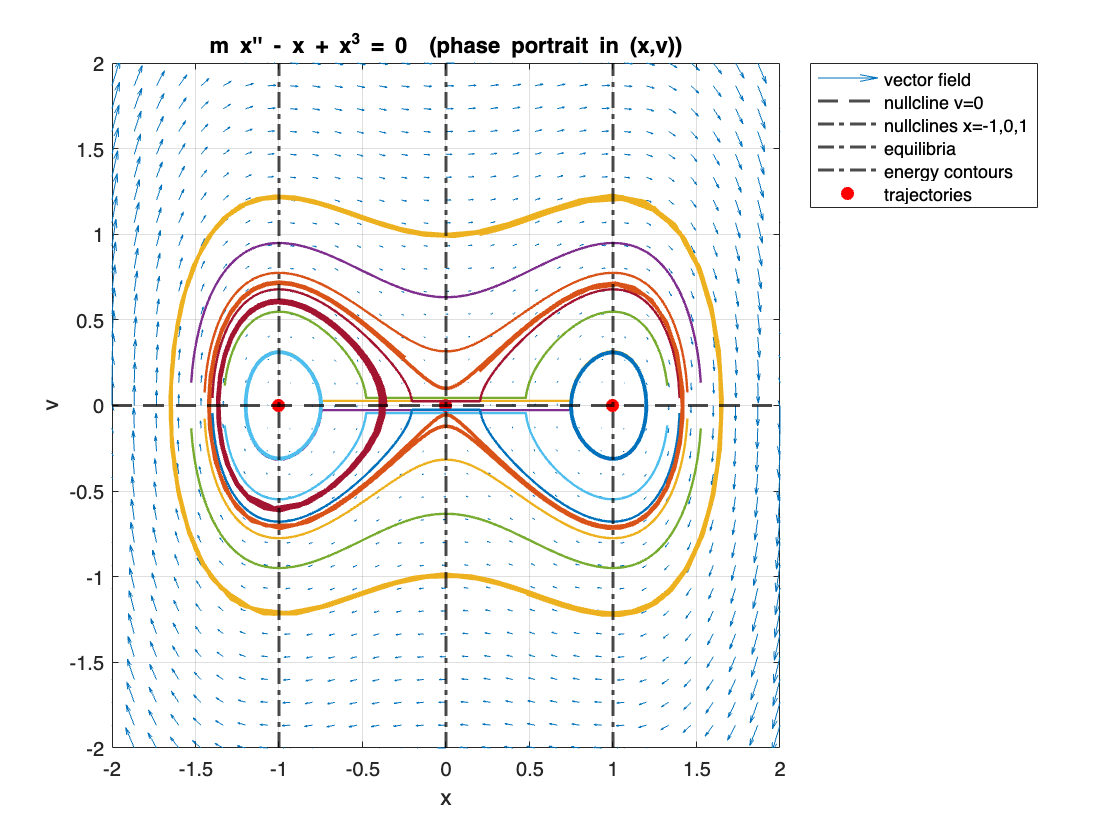

% Minima at x=±1, V=-1/4; maximum at x=0, V=0.

%% Phase portrait
xlimv = [-2 2];
vlimv = [-2 2];

[xg,vg] = meshgrid(linspace(xlimv(1),xlimv(2),31), linspace(vlimv(1),vlimv(2),31));
ug = vg;
wg = (1/m)*(xg - xg.^3);

figure('Color','w','Name','Example 4: Phase portrait');
hold on; box on; grid on;
quiver(xg,vg,ug,wg,'AutoScale','on');
xlabel('x'); ylabel('v');
title('m x'''' - x + x^3 = 0  (phase portrait in (x,v))');

% Nullclines:
% x' = 0 -> v=0
% v' = 0 -> x-x^3=0 -> x=0,±1
yline(0,'k--','LineWidth',1.4);
xline(-1,'k-.','LineWidth',1.4); xline(0,'k-.','LineWidth',1.4); xline(1,'k-.','LineWidth',1.4);

% Mark equilibria
plot(eq(:,1),eq(:,2),'ro','MarkerFaceColor','r','MarkerSize',6);

% Optional: plot a few energy contours (Hamiltonian level sets)
% Energy: E = (m/2)v^2 + V(x)
E_list = [-0.20 -0.10 -0.02 0.05 0.20];
for E = E_list
    % For each x, allowed v satisfies v^2 = (2/m)(E - V(x)) >= 0
    val = (2/m)*(E - V(xx));
    idx = val >= 0;
    if any(idx)
        vplus = sqrt(val(idx));
        vminus = -vplus;
        plot(xx(idx), vplus,'LineWidth',1.2);
        plot(xx(idx), vminus,'LineWidth',1.2);
    end
end

% Trajectories from several ICs
tspan = [0 30];
ICs = [ -1.2  0.0;
        -1.0  0.6;
         1.2  0.0;
         0.2  0.2;
         0.2  1.0];

for k=1:size(ICs,1)
    z0 = ICs(k,:)';
    [t,z] = ode45(f,tspan,z0);
    plot(z(:,1),z(:,2),'LineWidth',1.8);
end

xlim(xlimv); ylim(vlimv);
legend({'vector field','nullcline v=0','nullclines x=-1,0,1','equilibria',...
        'energy contours','trajectories'}, 'Location','bestoutside');


% (Optional teaching point)
% Energy should remain constant along trajectories (numerical drift is small with ode45 tolerances).